Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


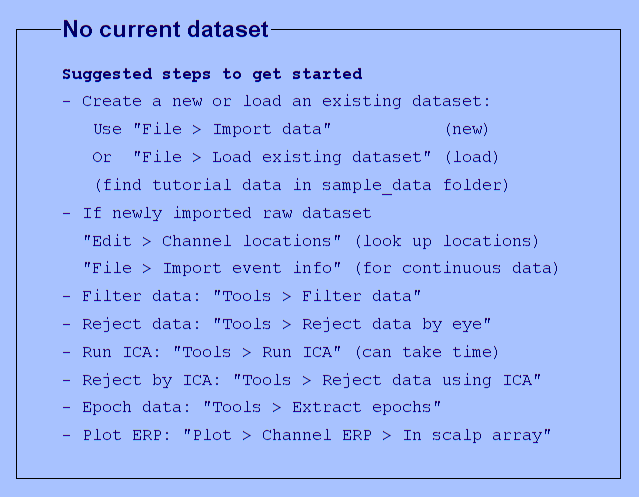

You are using the latest version of EEGLAB.


addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0'
eeglab;

referenced_preproce_name =  'referenced';
referenced_filename_wake_ses_types = {'wake_morning','wake_night'};
referenced_filename_sleep_ses_types = {'sleep'};
sleep_stages = {'N1','N2','N3','REM'};
referenced_set_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced';
referenced_event_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\elaborated_events';
output_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\mix_modeling';
referenced_elaboEvents_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\elaborated_events';
referenced_elaboEventsOutliers_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\elaborated_events+outliers';
subs = {'08','09','10','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

% create elaborated event file for referenced event files

outliers_results = cell(numel(subs), 4);
res_i = 1;
for sub_i=1:numel(subs)
    for ses_i=1:numel(referenced_filename_wake_ses_types)
        curr_ses = referenced_filename_wake_ses_types{ses_i};
        curr_sub = subs{sub_i};
        try 
            % get referenced file
            got_files = false;
            set_filename = sprintf('%s\\s_%s_%s_%s.set',referenced_set_dir,curr_sub,curr_ses,referenced_preproce_name);
            event_mat_filename = sprintf('%s\\s_%s_%s_%s_elaboEvents.mat',referenced_elaboEvents_dir,curr_sub,curr_ses,referenced_preproce_name);
            if isfile(set_filename)
                eeglab_referenced =  pop_loadset(set_filename);
                elaborated_events = load(event_mat_filename);
                elaborated_events = elaborated_events.events;
                output_filename = sprintf('%s\\s_%s_%s_%s_elaboEvents+outliers.mat',referenced_elaboEventsOutliers_dir,subs{sub_i},referenced_filename_wake_ses_types{ses_i},referenced_preproce_name);
                got_files = true;
            end
        catch ME
            strcat('could not get' ,set_filename)
            strcat('or' ,event_mat_filename)
            got_files = false;
        end
        if strcmp(subs{sub_i},'23') && strcmp(referenced_filename_wake_ses_types{ses_i},'wake_morning')
            continue;
        end
        if ~got_files  continue;  end


        data = eeglab_referenced.data;
        mean_sub_per_electd_over_time = mean(data,3);
        std_sub_per_electd_over_time = std(data,1,3);
        
        % Calculate the upper and lower thresholds per time and electrode
        upper_threshold = mean_sub_per_electd_over_time + 3.5 * std_sub_per_electd_over_time;
        lower_threshold = mean_sub_per_electd_over_time - 3.5 * std_sub_per_electd_over_time;
        
        % Create a matrix of ones with the same size as data
        ones_mat = ones(size(data));
        
        % Replicate the upper and lower thresholds across the third dimension of ones_mat
        upper_threshold_mat = bsxfun(@times, ones_mat, upper_threshold);
        lower_threshold_mat = bsxfun(@times, ones_mat, lower_threshold);
        
        % Count the number of electrodes exceeding the threshold per time x trial
        outlier_electrodes_count = sum((data > upper_threshold_mat) | (data < lower_threshold_mat), 1);
    
        % Find the trials which have 90% or more electrodes exceeding the threshold
        outlier_trials = squeeze(any(outlier_electrodes_count > 0.2*size(data,1), 2));

        % Update the cell array
        outliers_results{res_i, 1} = subs{sub_i}; 
        outliers_results{res_i, 2} = referenced_filename_wake_ses_types{ses_i}; 
        outliers_results{res_i, 3} = sum(outlier_trials);
        outliers_results{res_i, 4} = sum(outlier_trials)/length(outlier_trials);

        res_i = res_i+1;

        % update the new events table and save
        for j = 1:length(outlier_trials)
            elaborated_events(j).("is_outlier_trial") = outlier_trials(j);
        end
        events = elaborated_events;
        if ~isfolder(referenced_elaboEventsOutliers_dir)   mkdir(referenced_elaboEventsOutliers_dir); end
        save(output_filename,"events");   
    end
end

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_wake_morning_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_wake_morning_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_wake_night_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_wake_night_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...



disp(outliers_results);

    {'08'}    {'wake_morning'}    {[213]}    {[0.0444]}
    {'08'}    {'wake_night'  }    {[237]}    {[0.0494]}



outliers_results = cell(numel(subs), 4);
res_i = 1;
curr_ses = 'sleep';
for sub_i=1:numel(subs)
    curr_sub = subs{sub_i};
    try 
        % get referenced file
        got_files = false;
        set_filename = sprintf('%s\\s_%s_%s_%s.set',referenced_set_dir,curr_sub,curr_ses,referenced_preproce_name);
        event_mat_filename = sprintf('%s\\s_%s_%s_%s_elaboEvents.mat',referenced_elaboEvents_dir,curr_sub,curr_ses,referenced_preproce_name);
        if isfile(set_filename)
            eeglab_referenced =  pop_loadset(set_filename);
            elaborated_events = load(event_mat_filename);
            elaborated_events = elaborated_events.events;
            output_filename = sprintf('%s\\s_%s_%s_%s_elaboEvents+outliers.mat',referenced_elaboEventsOutliers_dir,curr_sub,curr_ses,referenced_preproce_name);
            got_files = true;
        end
    catch ME
        strcat('could not get' ,set_filename)
        strcat('or' ,event_mat_filename)
        got_files = false;
    end
    if ~got_files  continue;  end

    for stage_i = 1:numel(sleep_stages)
        if  strcmp(sleep_stages{stage_i}, "REM")
            indexes_value = find( strcmp({elaborated_events.('sleep_stage')},"Rt") | strcmp({elaborated_events.('sleep_stage')},"Rp"));
        else
            indexes_value = find(strcmp({elaborated_events.('sleep_stage')},sleep_stages{stage_i}));
        end

        data = eeglab_referenced.data(:,:,indexes_value);
        mean_sub_per_electd_over_time = mean(data,3);
        std_sub_per_electd_over_time = std(data,1,3);
        
        % Calculate the upper and lower thresholds per time and electrode
        upper_threshold = mean_sub_per_electd_over_time + 3.5 * std_sub_per_electd_over_time;
        lower_threshold = mean_sub_per_electd_over_time - 3.5 * std_sub_per_electd_over_time;
        
        % Create a matrix of ones with the same size as data
        ones_mat = ones(size(data));
        
        % Replicate the upper and lower thresholds across the third dimension of ones_mat
        upper_threshold_mat = bsxfun(@times, ones_mat, upper_threshold);
        lower_threshold_mat = bsxfun(@times, ones_mat, lower_threshold);
        
        % Count the number of electrodes exceeding the threshold per time x trial
        outlier_electrodes_count = sum((data > upper_threshold_mat) | (data < lower_threshold_mat), 1);
    
        % Find the trials which have 90% or more electrodes exceeding the threshold
        outlier_trials = squeeze(any(outlier_electrodes_count > 0.2*size(data,1), 2));
    
        % Update the cell array
        outliers_results{res_i, 1} = subs{sub_i}; 
        outliers_results{res_i, 2} = sleep_stages{stage_i}; 
        outliers_results{res_i, 3} = sum(outlier_trials);
        outliers_results{res_i, 4} = sum(outlier_trials)/length(outlier_trials);
    
        res_i = res_i+1;
    
        % update the new events table and save
        for j = 1:length(indexes_value)
            elaborated_events(indexes_value(j)).("is_outlier_trial") = outlier_trials(j);
        end
    end
    events = elaborated_events;
    if ~isfolder(referenced_elaboEventsOutliers_dir)   mkdir(referenced_elaboEventsOutliers_dir); end
    save(output_filename,"events");   
end

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_08_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_09_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_09_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_loadse


disp(outliers_results);

    {'08'}    {'N1' }    {[  78]}    {[0.0653]}
    {'08'}    {'N2' }    {[ 836]}    {[0.0641]}
    {'08'}    {'N3' }    {[  77]}    {[0.0203]}
    {'08'}    {'REM'}    {[ 201]}    {[0.0661]}
    {'09'}    {'N1' }    {[  80]}    {[0.0524]}
    {'09'}    {'N2' }    {[1165]}    {[0.0727]}
    {'09'}    {'N3' }    {[ 154]}    {[0.0238]}
    {'09'}    {'REM'}    {[ 152]}    {[0.0283]}
    {'10'}    {'N1' }    {[  58]}    {[0.0479]}
    {'10'}    {'N2' }    {[ 890]}    {[0.0591]}
    {'10'}    {'N3' }    {[  78]}    {[0.0200]}
    {'10'}    {'REM'}    {[ 107]}    {[0.0261]}
    {'11'}    {'N1' }    {[  66]}    {[0.0768]}
    {'11'}    {'N2' }    {[ 550]}    {[0.0575]}
    {'11'}    {'N3' }    {[  91]}    {[0.0198]}
    {'11'}    {'REM'}    {[ 146]}    {[0.0377]}
    {'13'}    {'N1' }    {[ 135]}    {[0.0694]}
    {'13'}    {'N2' }    {[1196]}    {[0.0718]}
    {'13'}    {'N3' }    {[ 120]}    {[0.0220]}
    {'13'}    {'REM'}    {[ 205]}    {[0.0438]}
    {'14'}    {'N1' }    {[ 272]}    {[0